# MPEG LAYER II

### Read File:

file = 'listen-to-the-ancient-egyptions-tv .wav';
[signal,Fs] = audioread(file);
file_info = audioinfo(file)

file_info = struct with fields:
             Filename: '/home/ozi/Desktop/MPEG-Audio-Compression/listen-to-the-ancient-egyptions-tv .wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 240000
             Duration: 10
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


bps = file_info.BitsPerSample;
sound(signal,Fs);

### Get Filter Coefficients

num_filters= 32;
filter_order=512;
h_all = zeros(num_filters,filter_order);
h_coeffs = PQMF_ReadCoeffs();

Error using fscanf
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in PQMF_ReadCoeffs (line 11)
PQMF_Coeffs = fscanf(coeff_file,formatSpecs,matSize);

plot([0:512],h_coeffs)
grid on
title('h[n]')
xlabel('n')
ylabel('h[n]')

### Getting all modulated filters:

According to this equation:

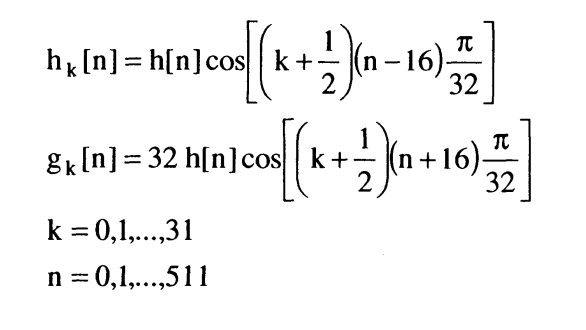

(Bosi, Goldberg, sect 4.2)

for k= 0 :num_filters-1
    for n=0: filter_order-1
        h_all(k+1,n+1) = h_coeffs(n+1) * cos((k+(1/2)*(n-16)*(pi/32)));
    end
end

subplot(2,2,1)
plot([0:511],h_coeffs(1:512))
title('h[n]')
xlabel('n')
ylabel('h[n]')
subplot(2,2,2)
plot([0:511],h_all(1,:))
title('h_0[n]')
xlabel('n')
ylabel('h_0[n]')
subplot(2,2,3)
plot([0:511],h_all(2,:))
title('h_1[n]')
xlabel('n')
ylabel('h_1[n]')
subplot(2,2,4)
plot([0:511],h_all)
title('all h_k[n]')
xlabel('n')
ylabel('h_all[n]')

### Now, Let's filter the signal:

sig_filtered =[];
for k=0:1:31
    sig_f= filter(h_all(k+1,:),1,signal);  %Filtering 
    sig_down = downsample(sig_f,32);       %Down Sampling
    sig_filtered=[sig_filtered sig_down];  %Appending
end
